path = ["A324_2023_07_19a";
    "A324_2023_07_20";
    "A324_2023_07_21";
    "A324_2023_07_22";
    "A324_2023_07_23";
    "A324_2023_07_24";
    "A324_2023_07_25";
    "A327_2023_08_31";
    "A327_2023_09_01";
    "A327_2023_09_02";
    "A327_2023_09_03";
    "A327_2023_09_04";
    "A327_2023_09_08";
    "C211_2023_12_14";
    "C211_2023_12_17";
    "C211_2023_12_18";
    "C211_2023_12_19";
    "C211_2023_12_30";
    "C211_2023_12_31"];

addpath("/Users/ks0106/Desktop/");
addpath("/Users/ks0106/Desktop/rotation 2/Codes/");
addpath("/Users/ks0106/Desktop/myProject/scripts/");
addpath("/Users/ks0106/Desktop/myProject/scripts/functions/");

region = "M1";

subtract_aft = 0; % 0: subtract before; 1: subtract after; 2: delta_click use gamma

session = repmat(struct(),length(path),1);
for i = 1:length(path)
    load("/Users/ks0106/Desktop/rotation 2/Data/DVs_causal_smoothing/" + path(i) + "_DVs.mat");
    region_idx = find([res{1,1}.region]==region);
    if isempty(region_idx)
        continue
    end
    % gamma: (ntrials,1)
    gamma = res{1,1}(1).Trials.gamma;
    % first click: (ntrials, 1)
    first_click = res{1,1}(1).Trials.stateTimes.first_click;
    nTcName = "committime_s_" + region;
    % nTc: (ntrials, 1)
    nTc = res{1,1}(1).Trials.stateTimes.(nTcName);

    % choice: (ntrials, 1)
    choice = res{1,1}(1).Trials.pokedR;

    % delta_clicks: (ntrials, ntimes); bin_centers: (1, ntimes)
    [delta_clicks, time_DC] = get_binned_delta_clicks(res{1,1}(1).Trials, 'interval', [0, 1]);

    % subtract mean
    switch subtract_aft
        case 0
            unique_gamma = unique(gamma);
            choice_centered = zeros(size(choice));
            delta_clicks_centered = zeros(size(delta_clicks));
        
            for j = 1:length(unique_gamma)
                idx = (gamma == unique_gamma(j));
                choice_centered(idx) = choice(idx) - mean(choice(idx));
                delta_clicks_centered(idx, :) = delta_clicks(idx, :) - mean(delta_clicks(idx, :), 1, 'omitnan');
            end
        
            % choose trials with valid nTc
            trial_idx = find(~isnan(nTc));
        
            gamma = gamma(trial_idx);
            nTc = nTc(trial_idx);
            first_click = first_click(trial_idx);
            choice = choice(trial_idx);
            delta_clicks = delta_clicks(trial_idx,:);
            choice_centered = choice_centered(trial_idx,:);
            delta_clicks_centered = delta_clicks_centered(trial_idx,:);
        case 1
            % choose trials with valid nTc
            trial_idx = find(~isnan(nTc));
        
            gamma = gamma(trial_idx);
            nTc = nTc(trial_idx);
            first_click = first_click(trial_idx);
            choice = choice(trial_idx);
            delta_clicks = delta_clicks(trial_idx,:);
    
            unique_gamma = unique(gamma);
            choice_centered = zeros(size(choice));
            delta_clicks_centered = zeros(size(delta_clicks));
            
            for j = 1:length(unique_gamma)
                idx = (gamma == unique_gamma(j));
                choice_centered(idx) = choice(idx) - mean(choice(idx));
                delta_clicks_centered(idx, :) = delta_clicks(idx, :) - mean(delta_clicks(idx, :), 1, 'omitnan');
            end

        otherwise
            disp('Wrong input');
    end

    % realign data
    thre_clicks_bef = -0.4;
    thre_clicks_aft = 0.3;
    % the whole aligned matrix
    nTc_fc = nTc - first_click;
    [delta_clicks_all_aligned, time_to_nTc] = realign_data_mom(delta_clicks_centered, time_DC, nTc_fc);
    time_to_nTc = round(time_to_nTc,2);
    % Column for delta_clicks
    clicks_idx = find(time_to_nTc >= thre_clicks_bef & time_to_nTc <= thre_clicks_aft);
    session(i).delta_clicks_aligned = delta_clicks_all_aligned(:, clicks_idx);
    % choice
    session(i).choice = choice;
    session(i).choice_centered = choice_centered;
end

choice_uncentered = [];
choice_centered = [];
delta_clicks_aligned = [];
for i = 1:length(path)
    choice_uncentered = [choice_uncentered; session(i).choice];
    choice_centered = [choice_centered; session(i).choice_centered];
    delta_clicks_aligned = [delta_clicks_aligned; session(i).delta_clicks_aligned];
end

% time aligned
time_clicks = round(thre_clicks_bef:0.05:thre_clicks_aft,2);

# Compute

#### the correlation matrix

corr_vec = zeros(size(delta_clicks_aligned,2),1);
corr_num = zeros(size(delta_clicks_aligned,2),1);
r_lower = zeros(size(delta_clicks_aligned,2),1);
r_upper = zeros(size(delta_clicks_aligned,2),1);

for j = 1:size(delta_clicks_aligned,2)
    % trial index
    idx = ~isnan(delta_clicks_aligned(:,j));
    % correlation matrix
    corr_vec(j) = corr(choice_centered(idx), delta_clicks_aligned(idx,j));
    % number of trials in the pixel
    corr_num(j) = sum(idx);

    z = 0.5 * log((1+corr_vec(j))/(1-corr_vec(j)));
    se_z = 1/sqrt(corr_num(j)-3);

    z_lower = z - 1.96*se_z;
    z_upper = z + 1.96*se_z;

    r_lower(j) = tanh(z_lower);
    r_upper(j) = tanh(z_upper);
end

# Figure

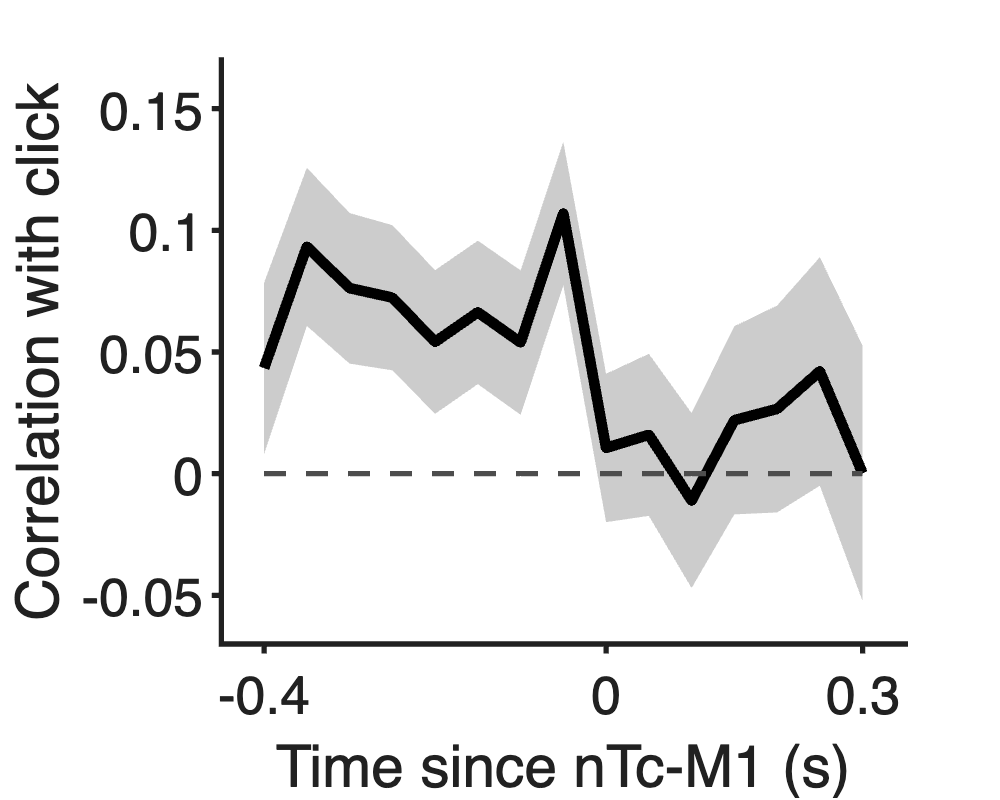

figure('Position', [200, 200, 500, 400])
clf;

fill([time_clicks, fliplr(time_clicks)], [r_upper', fliplr(r_lower')], ...
    [0.8 0.8 0.8], 'EdgeColor', 'none', 'FaceAlpha', 1); hold on;

plot(time_clicks, corr_vec, 'LineWidth', 4, 'Color', 'k'); hold on;
plot(time_clicks, linspace(0, 0, length(time_clicks)), 'LineStyle', '--', 'LineWidth', 2, 'Color', [0.3, 0.3, 0.3]); hold on;

ax = gca;
ax.LineWidth = 2; 
ax.XTick = [-0.4 0 0.3];
ax.YTick = [-0.1 -0.05 0 0.05 0.1 0.15 0.2];
% ax.YTick = [-0.2 -0.1 0 0.1 0.2 0.3];
xlim([-0.45, 0.35]);
ylim([-0.07, 0.17]);
box off
set(gca, 'TickDir', 'out')

xlabel("Time since nTc-" + region + " (s)");
ylabel('Correlation with click');
set(gca, 'FontSize', 20);
exportgraphics(gcf, "/Users/ks0106/Desktop/click choice correlation single region/" + region + ".pdf", 'ContentType', 'vector', 'BackgroundColor', 'none');